# Observation of Kelvin--Helmholtz billows in the marine atmospheric boundary layer using ship-borne Doppler wind lidar data

This Live Script illustrates selected processing steps for ship-borne Doppler wind lidar observations from the LOLland offshore Lidar EXperiment (LOLLEX), with focus on the Kelvin--Helmholtz billow event observed on 22 February 2023 and analysed by Malekmohammadi et al. (2025a). The campaign was conducted from September 2022 to August 2023 in and around the Rødsand II offshore wind farm, south of Lolland, Denmark. During LOLLEX, Doppler wind lidars were deployed on a crew transfer vessel commuting between Rødbyhavn and the wind farm. This mobile platform enabled repeated observations inside, near, and outside the wind farm.

The WindCube 100S scanning lidar was operated in a repeating sequence of approximately 25 min of fixed vertical line-of-sight measurements followed by 5 min of Doppler Beam Swinging (DBS) wind profiling. The fixed vertical-stare scan provides high-temporal-resolution line-of-sight velocity and carrier-to-noise ratio (CNR) profiles. The preceding DBS scan provides the mean horizontal wind-speed profile used here to correct the vertical-stare velocity for a static beam tilt.

The purpose of this script is not to reproduce the full processing chain of the paper. Instead, it demonstrates how to read the NetCDF files, apply basic CNR-based filtering, compare the DBS mean wind-speed profile with NORA3 data, correct the fixed-LOS velocity using a static tilt angle of 2.7 degrees, and visualise the KHB event using time-height plots of CNR, static-tilt-corrected vertical velocity, and the 60 s moving standard deviation of the vertical velocity. The script also estimates vertical profiles of $\sigma_w$ and $\kappa_w$ and spectral estimates of the vertical velocity before, during, and after the KHB event.

The full LOLLEX dataset is planned to be made available in 2026. The exact release date will depend on the publication timeline of the companion LOLLEX paper (Malekmohammadi et al. 2025b)

**Important Note**

The purpose of this Live Script is to provide a lightweight, educational example of how selected results from Malekmohammadi et al. (2025a) can be reproduced from the released example files using minimal processing. The code provided here is **not** the original analysis code used in the paper, and it does not reproduce the full processing chain, quality-control procedure, stationarity assessment, spectral analysis, or contextual meteorological analysis described in the publication. The scientific results, methodology, and interpretation should therefore be taken from the paper itself, not from this simplified script.

This Live Script was prepared by E. Cheynet as a companion example for data exploration and visualisation. It should not be interpreted as documenting the full analysis work carried out for the KHB paper or the LOLLEX campaign paper. In particular, the primary data processing, campaign data curation, scientific analysis, and thesis-related work associated with these studies are described in Malekmohammadi et al. (2025a,b) and in the associated PhD work.

**References**

Malekmohammadi, S., Cheynet, E., & Reuder, J. (2025a). *Observation of Kelvin--Helmholtz billows in the marine atmospheric boundary layer by a ship-borne Doppler wind lidar*. Scientific Reports, 15, 5245. doi:10.1038/s41598-025-89554-4

Malekmohammadi, S., Cheynet, E., Reuder, J., Linnemann, C., Sjöholm, M., Mann, J., & Giebel, G. (2025b). *The LOLland offshore Lidar EXperiment (LOLLEX): A novel observational approach for the study of wind farm flow and entrainment*. EGUsphere [preprint]. doi:10.5194/egusphere-2025-3148

## Plot the topography around the site

This map provides geographical context for the LOLLEX campaign. The background topography and bathymetry are based on GEBCO data. The red points indicate available measurement locations from the open-database file, while Copenhagen and Rødbyhavn are shown as geographical references.

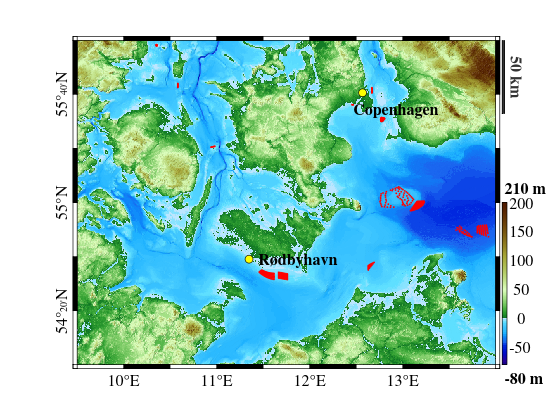

clearvars
close all
clc
addpath('./functions')
addpath('./data')
databaseFile = "20251218_eww_opendatabase.csv";
gebcoFile = "gebco_2025_n57.0_s53.0_w9.0_e14.0.nc";
% [lonMin lonMax latMin latMax]
bbox = [9.5 14 54 56];
plotLollexTopography(gebcoFile,databaseFile,bbox)

## Read DBS scan

The DBS scan immediately preceding the vertical stare scan is used to estimate the horizontal mean wind-speed profile. This profile is needed for the static tilt correction of the vertical LOS velocity.

minCNR = -27;
fs = 1;

clear DBS
filename = ['WLS100s-37_2023-02-22_12-30-02_dbs_229_25m.nc'];
sweepGrp = char(ncread(filename,'sweep_group_name'));
tst = ncread(filename,[sweepGrp,'/timestamp']);
DBS.time = datetime(tst,'InputFormat','yyyy-MM-dd''T''HH:mm:ss.SSS''Z''');
nt = numel(DBS.time);
DBS.z = mean(ncread(filename,[sweepGrp,'/measurement_height']),2,'omitnan')';
DBS.CNR = ncread(filename,[sweepGrp,'/cnr'])';
DBS.dispersion= ncread(filename,[sweepGrp,'/doppler_spectrum_width'])';
DBS.u = ncread(filename,[sweepGrp,'/horizontal_wind_speed'])';
DBS.w = ncread(filename,[sweepGrp,'/vertical_wind_speed'])';
DBS.wind_direction= ncread(filename,[sweepGrp,'/wind_direction'])';
DBS.wind_speed_status = ncread(filename,[sweepGrp,'/wind_speed_status'])';
DBS.lat = ncread(filename,'latitude');
DBS.lon = ncread(filename,'longitude');
DBS.default_lat = ncread(filename,'default_latitude');
DBS.default_lon = ncread(filename,'default_longitude');

% Basic cleaning
DBS.wind_direction(abs(DBS.u)>30)= nan;
DBS.w(abs(DBS.u)>30)= nan;
DBS.u(abs(DBS.u)>30)= nan;
DBS.wind_direction(DBS.CNR<minCNR)=nan;
DBS.u(DBS.CNR<minCNR)=nan;
DBS.w(DBS.CNR<minCNR)=nan;

## Read fixed LOS scan

This scan corresponds to the continuous vertical stare period during which the KHB event was observed. In vertical stare mode, the WindCube 100S measures the along-beam velocity. Since the beam is close to vertical, this velocity approximates the vertical velocity component, after correction for static tilt.

filename = ['WLS100s-37_2023-02-22_12-35-04_fixed_228_25m.nc'];
% ncdisp(filename);
try
    sweepGrp = char(ncread(filename,'sweep_group_name'));
catch exception
    finfo = ncinfo(filename);
    dummy={finfo.Groups.Name};
    sweepGrp = char(dummy{2});
end
clear WLS
tst = ncread(filename,[sweepGrp,'/time']);
tst = seconds(tst) + datetime(1970,1,1,0,0,0);
WLS.time = tst;
WLS.azimuth = ncread(filename,[sweepGrp,'/azimuth'])'; % azimuth angle
WLS.elevation = ncread(filename,[sweepGrp,'/elevation'])'; % elevation angle
WLS.vr = ncread(filename,[sweepGrp,'/radial_wind_speed'])';
WLS.r = 50+10.*ncread(filename,[sweepGrp,'/gate_index'])'; % minimum height of 50 m
WLS.CNR = ncread(filename,[sweepGrp,'/cnr'])';
WLS.dispersion= ncread(filename,[sweepGrp,'/doppler_spectrum_width'])';
WLS.lat = ncread(filename,'latitude');
WLS.lon = ncread(filename,'longitude');
WLS.default_lat = ncread(filename,'default_latitude');
WLS.default_lon = ncread(filename,'default_longitude');

% Basic cleaning
WLS.vr(WLS.CNR<minCNR)= nan;
WLS.vr(abs(WLS.vr)>30)= nan;

## Mean wind speed profiles

This section compares the mean horizontal wind-speed profile estimated from the WindCube 100S DBS scan with the corresponding NORA3 profile around the time of the KHB event. The DBS profile provides the local wind-speed estimate before the vertical-stare scan, whereas NORA3 provides a coarser atmospheric reference over the same period. The comparison is useful for checking the vertical wind-speed structure before the KHB event and for estimating the mean horizontal wind speed used in the static tilt correction of the fixed-LOS velocity.

The interpretation of DBS data below approximately 200 m should be made with caution because the vessel was located close to a wind turbine during the event. In this height range, the flow may be affected by the near wake of the turbine, and the assumptions of horizontal homogeneity and stationarity required for DBS wind profiling may be less valid.

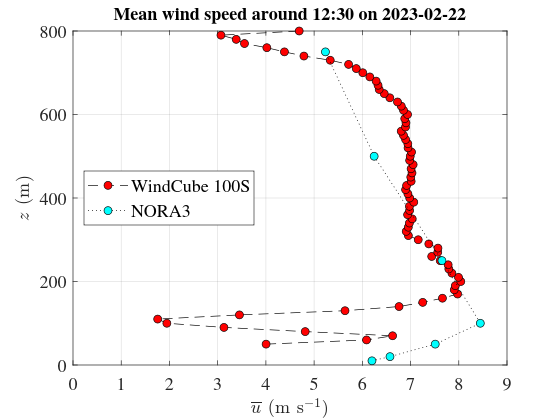

% Read NORA3 data
NORA3 = load('NORA3_2022_2023_locationMatching_filled.mat');
indT = find(NORA3.time>datetime(2023,02,22,11,55,0) & NORA3.time<datetime(2023,02,22,13,05,0));
zmin = 0;
zmax = 800;
clf;close all;
figure
meanU = mean(DBS.u,'omitnan');
plot(meanU,DBS.z,'ko--','markerfacecolor','r')
hold on
plot(mean(NORA3.U(indT,:)),NORA3.z,'ko:','markerfacecolor','c')
legend('WindCube 100S', 'NORA3','location','west')
title('Mean wind speed around 12:30 on 2023-02-22')
ylabel('$z$ (m)','interpreter','latex')
xlabel('$\overline{u}$ (m~s$^{-1}$)','interpreter','latex')
ylim([zmin zmax])
xlim([0 9])
grid on
set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')

## Correction for static tilt error

Because the WindCube 100S was operated in vertical stare mode, only one LOS velocity component is available and a full motion correction cannot be applied. The script therefore applies only the static tilt correction used in the KHB paper:


$$w_c = w_\mathrm{LOS}\cos\theta - \overline{u}\sin\theta$$


where  $\theta = 2.7^\circ$and $\overline{u}$ is the mean wind speed interpolated from the preceding DBS profile.

tilt = 2.7; % deg
% Interpolate DBS mean horizontal wind speed onto fixed-LOS heights
meanU_WLS = interp1(DBS.z,meanU,WLS.r,'linear');
WLS.vr_corrected = WLS.vr.*cosd(tilt) -meanU_WLS.*sind(tilt);

## Time-height visualisation of the vertical-stare scan

This section visualises the fixed vertical-stare scan as time-height plots. The first panel shows the carrier-to-noise ratio (CNR), which is used here as a proxy for aerosol backscatter. The KHB structures are visible as coherent, wave-like patterns in the aerosol layer. The second panel shows the static-tilt-corrected line-of-sight velocity, interpreted as an approximation of the vertical velocity. The third panel shows the 60 s moving standard deviation of the vertical velocity, which highlights the transient increase in vertical turbulence during the KHB event.

The visualisation emphasises the period during which the billows were advected through the lidar beam. In the KHB paper, the event is identified mainly between about 12:46 and 12:56 UTC and between roughly 550 and 750 m above the surface. The CNR field helps identify the coherent billow structures, while the velocity and $\sigma_w$ fields show the associated vertical motions and enhanced turbulence.

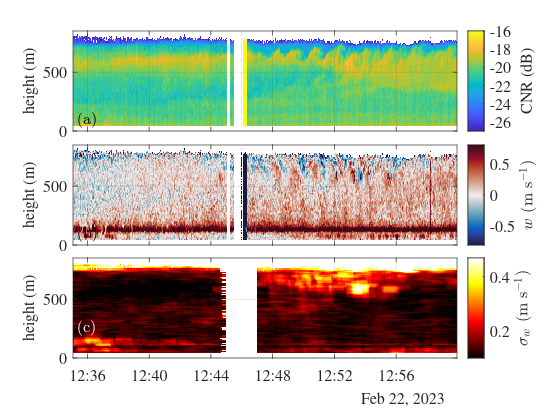

zmin = 0; % min height in metres
zmax = 850; % max height in metres
indZ = find(WLS.r<zmax & WLS.r>zmin);

clf;close all;
figure
tiledlayout(3,1,'tilespacing','tight')

nexttile
dummy0 = (WLS.CNR(1:end,indZ)); % isnan
dummy0 = single(dummy0);
dummy0 = dummy0' -mean(dummy0','omitnan') + movmean(mean(dummy0','omitnan'),40,'omitnan');
dummy0(isnan(WLS.vr(:,indZ)')) = nan;
imagescn(WLS.time,WLS.r(indZ),dummy0);
colormap('parula')
set(gcf,'Color','w')
set(gca,'xTicklabels',[])
c1 = colorbar;
clim([-27 -16])
ylim([0,round(max(WLS.r(indZ))/10)*10])
ylabel(c1,'CNR (dB)')
ylabel('height (m)')
grid on
ylim([zmin zmax])
xlim([WLS.time(1),WLS.time(end)])
label('(a)',0.01,0.01,'Color','k');
%%%%%%%%%%%%%%%%%
nexttile
dummy0 = WLS.vr_corrected(1:end,indZ);
dummy0 = single(dummy0);
dummy0 = dummy0' -mean(dummy0','omitnan') + movmean(mean(dummy0','omitnan'),40,'omitnan');
dummy0(isnan(WLS.vr(:,indZ)')) = nan;
imagescn(WLS.time(1:end),WLS.r(indZ),dummy0);
cmocean('balance')
c2 = colorbar;
set(gcf,'Color','w')
q = min(3,quantile(abs(WLS.vr(:)),0.9));
clim([-q,q])
ylim([0,round(max(WLS.r)/10)*10])
ylabel('height (m)')
ylabel(c2,'$w$ (m s$^{-1}$)','interpreter','latex')
grid on
ylim([zmin zmax])
set(gca,'xticklabels',[])
xlim([WLS.time(1),WLS.time(end)])

label('(b)',0.01,0.01,'Color','k');
%%%%%%%%%%%%%%%%%%%%%%%
% Standard deviation of the vertical velocity estimated using a
% centred sliding window of 60 s
nexttile
dummy0 = WLS.vr_corrected(:,indZ);
stdVr = movstd(fillgaps(dummy0,20),60,1,'includenan');
stdVr(isnan(dummy0)) = nan;

stdVr(WLS.time>datetime(2023,02,22,12,45,0,0) & WLS.time<datetime(2023,02,22,12,47,0,00),:) = nan;
stdVr(WLS.time>datetime(2023,02,22,13,15,0,0) & WLS.time<datetime(2023,02,22,13,17,0,00),:) = nan;
stdVr(WLS.time>datetime(2023,02,22,13,21,15,0) & WLS.time<datetime(2023,02,22,13,22,15,00),:) = nan;

imagescn(WLS.time(1:end),WLS.r(indZ),stdVr');
colormap(gca,'hot')
set(gcf,'Color','w')
c3 = colorbar;
q99 = quantile(abs(stdVr(:)),0.99);
clim([0.1,q99])
ylim([zmin zmax])
ylabel(c3,'$\sigma_w$ (m s$^{-1}$)','Interpreter','latex')
ylabel('height (m)')
grid on 
label('(c)',0.01,0.20,'Color','w');
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')

## Profiles of standard deviation and kurtosis, and PSD estimates at 650 m

The following turbulence statistics are computed from the fixed-LOS velocity after gap filling and linear detrending. Since the static tilt correction mainly introduces a height-dependent offset and a negligible scaling factor of $\cos(2.7^\circ)$, the estimated standard deviation, kurtosis and PSD are nearly identical whether they are computed from `WLS.vr` or `WLS.vr_corrected`. The correction is therefore more important for visualising the mean vertical velocity field than for the detrended turbulence statistics shown below.

fs = 1;
height_target = 650;
[~,indR] = min(abs(WLS.r-height_target));
indT_stdW{1} = find(WLS.time>=datetime('22-Feb-2023 12:35:00') & WLS.time<=datetime('22-Feb-2023 12:44:30')) ; % before
indT_stdW{2} = find(WLS.time>=datetime('22-Feb-2023 12:47:00') & WLS.time<=datetime('22-Feb-2023 12:56:00')) ; % during
indT_stdW{3} = find(WLS.time>=datetime('22-Feb-2023 12:56:00') & WLS.time<=datetime('22-Feb-2023 13:00:00')) ; % after

leg = {'Before KHB','During KHB','After KHB'};

clf;close all;
figure('position',[500,500,800,300])
tiledlayout(1,3,"TileSpacing","loose")
%%%%%%%%%%%%%%%% TILE 1 %%%%%%%%%%%%%%%%%%%
nexttile
[N,Nz]=size(WLS.vr);
for ii=1:3
    dummy= fillgaps(WLS.vr(indT_stdW{ii},:),20);
    percNaN = zeros(1,Nz);
    for jj=1:Nz
        percNaN(jj) = mean(isnan(WLS.vr(indT_stdW{ii},jj)));
    end
    stdY = std(detrend(dummy,'omitnan'),'omitnan');
    stdY(percNaN>0.1) = nan;
    plot(stdY,WLS.r,'linewidth',1.2)
    hold on
end

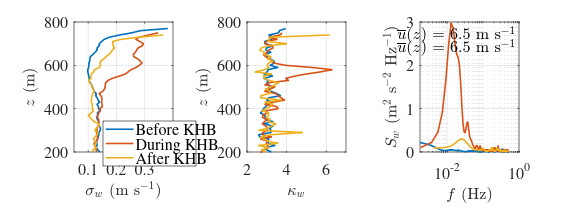

l = legend(leg{:},'location','southeast');
set(gcf,'color','w')
grid on
xlim([0.05,0.4])
ylim([200 800])
l.Position = [0.18    0.2301    0.1625    0.2082];
clear leg
ylabel('$z$ (m)','interpreter','latex')
xlabel('$\sigma_w$ (m s$^{-1}$)','interpreter','latex')

%%%%%%%%%%%%%%%% TILE 2 %%%%%%%%%%%%%%%%%%%
nexttile
for ii=1:3,
    dummy= fillgaps(WLS.vr(indT_stdW{ii},:),20);
    percNaN = zeros(1,Nz);
    for jj=1:Nz,
        percNaN(jj) = mean(isnan(WLS.vr(indT_stdW{ii},jj)));
    end
    kurtY = kurtosis(detrend(dummy));
    kurtY(percNaN>=0.1) = nan;
    plot(kurtY,WLS.r,'linewidth',1.2)
    hold on
end
set(gcf,'color','w')
grid on
xlim([2 7])
ylim([200 800])
ylabel('$z$ (m)','interpreter','latex')
xlabel('$\kappa_w$','interpreter','latex')

%%%%%%%%%%%%%%%% TILE 3 %%%%%%%%%%%%%%%%%%%
nexttile
for ii=1:3
    dummy= WLS.vr(indT_stdW{ii},indR);
    N0 = numel(dummy);
    [S,f]=pwelch(detrend(dummy),round(N0/3),round(N0/6),round(N0),fs);
    semilogx(f,S,'linewidth',1.2)
    hold on
end
set(gcf,'color','w')
grid on
ylabel('$S_w$ (m$^2$ s$^{-2}$ Hz$^{-1}$)','interpreter','latex')
xlabel('$f$ (Hz)','interpreter','latex')
txt = sprintf('$\\overline{u}(z)$ = %2.1f m s$^{-1}$',meanU_WLS(indR));
label(txt,0.97,0.87,'verticalalignment','top','alignment','right');
txt = sprintf('$\\overline{u}(z)$ = %2.1f m s$^{-1}$',meanU(indR));
label(txt,0.97,0.97,'verticalalignment','top','alignment','right');
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')